l=1; t=1;
filepath='Z:\data\24-08-29iEMG-US-sEMG联合采集_程瑞佳\';
% eaf_name=[ 'Z:\Result\24-10-12iEMG-sEMG\M' num2str(l) 'L1T' num2str(t) '.eaf'];
% iemg_name=[ 'Z:\data\24-10-12iEMG-sEMG\M' num2str(l) 'L1T' num2str(t) '.mat'];
eaf_name=['Z:\data\24-6-21iEMG-US-sEMG联合采集_康亦铭右肱二头\signal\iEMG_US肌电后处理\iEMG_S1_M1_level' num2str(l) '_trial' num2str(t) '_24-06-21_UUS.eaf'];
iemg_name=['Z:\data\24-6-21iEMG-US-sEMG联合采集_康亦铭右肱二头\signal\iEMG_US肌电后处理\iEMG_S1_M1_level' num2str(l) '_trial' num2str(t) '_24-06-21_UUS.mat'];

% load('Z:\Result\24-08-22iEMG-US-sEMG联合采集__胡康生右肱二头肌\822_HKS_xEMG_CBSS_decomp.mat')
% load('Z:\Result\24-08-29iEMG-US-sEMG联合采集_程瑞佳\829_xEMG_CKC_decomp_filtfilt.mat')
iEMG=importdata(iemg_name);
eafdata=importdata(eaf_name);
iemgcell{1}=downsample(double(iEMG.Data{1}(:,1)),5);

此类型的变量不支持使用点进行索引。




ckc=draw_PluseTime(CKCdecomp{l,t}.MUPulses,2048,5);
title(['ckc M2L' num2str(l) 'T' num2str(t)])

%将iEMG降采样至2048Hz,绘制图像
fsampu=10240;%iEMG的采样率
muNum = max(eafdata.data(:,2)); % MU的个数
iPulses = {};
for mu = 1:muNum
    % iPulses就是这个eaf文件里分解得到的spike train，每个cell表示一个MU，里面的数字是该MU每次放电的时刻
    iPulses{mu} = round(eafdata.data(find(eafdata.data(:,2)==mu),1)'*fsampu/5);
end
iemg=draw_PluseTime(iPulses,2048);
title(['iEMG M2L' num2str(l) 'T' num2str(t)])

% iEMG=downsample(data_EMG,5);iemgcell{1}=iEMG;%iEMG原始信号



单独对比

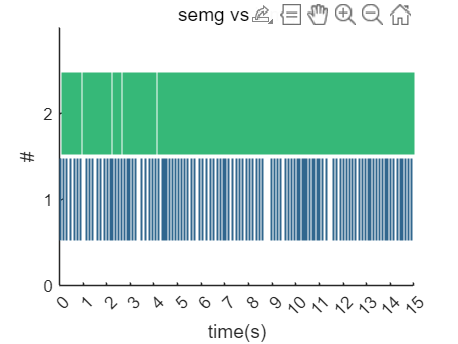

% compare{2}=CBSSdecomp{l,t}{1};
compare{2}=SPT{1};
% compare{1}=iPulses{1};
compare{1}=iPulses{1};
draw_PluseTime(compare,2048,1,2000,1,1);
title('semg vs iemg')

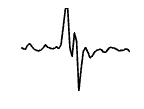

%iemgPT 求MUP

muaps=muapExtraction(iemgcell,iPulses,50,'STA');
figure;clf;
plotArrayPotential(muaps{4},1,1);

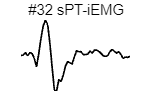

%semgPT 求MUP
which=32;
SPT{1}=CKCdecomp{l,t}.MUPulses{which};
for i=1:length(SPT{1})
    SPT{1}(1,i)=SPT{1}(1,i);%减去lag
end

muaps=muapExtraction(iemgcell,SPT,50,'STA');
figure;clf;
plotArrayPotential(muaps{1},1,1);
% title(['M2L' num2str(l) 'T' num2str(t) ' CKC#' num2str(which) ' STAiEMG' ])
title(['#' num2str(which) ' sPT-iEMG' ])

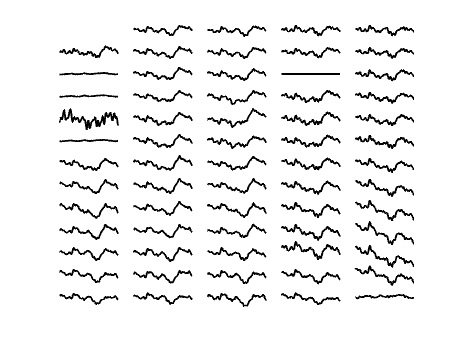

%iemgPT 求MUAParray
datafilt=CKCdecomp{l,t}.datafilt;
[sigcell]=sig2cell(datafilt,4);
muaparray=muapExtraction(sigcell,iPulses,100,'STA');
figure;clf
muap_recon=muap_pca(muaparray{1},0.9);
figure;
plotArrayPotential(muap_recon,1,1);

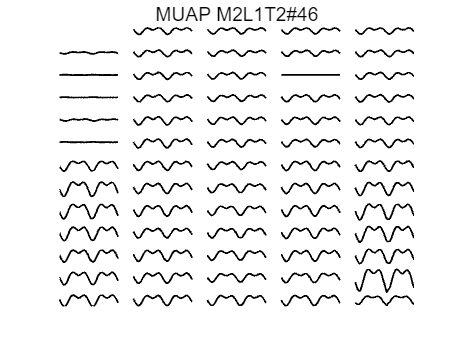

muaparray=muapExtraction(sigcell,CKCdecomp{l,t}.MUPulses,100,'STA');
figure;clf
muap_num=46;
muap_recon=muap_pca(muaparray{muap_num},0.9);
figure;
plotArrayPotential(muap_recon,1,1);
title(['MUAP M2L' num2str(l) 'T' num2str(t) '#' num2str(muap_num)])

导出ann文件

fsamp_sEMG=2048;
PT=CKCdecomp{l,t}.MUPulses{13};
filename='12.ann'
pt2ann(PT,fsamp_sEMG,filename)
